% load dataset
load toy.dat

[N, I] = size(toy)

N = 10

I = 3

X = [ones(N, 1), toy(:, 1:2)] % apply ones on the column to account for biases in weights vector

X =     1.0000    2.0000    3.0000
    1.0000    3.0000    2.0000
    1.0000    3.0000    6.0000
    1.0000    5.5000    4.5000
    1.0000    5.0000    3.0000
    1.0000    7.0000    4.0000
    1.0000    5.0000    6.0000
    1.0000    8.0000    6.0000
    1.0000    9.5000    5.0000
    1.0000    9.0000    7.0000


targets = toy(:, 3) % targets is third column

targets =      0
     0
     0
     0
     0
     1
     1
     1
     1
     1



proposalWidth = 0.1

proposalWidth = 0.1000

alpha = 0.01;

% Define posterior distribution for W
y = @(W) sigmoid(X * W)  %N x 1

y = function_handle with value:
    @(W)sigmoid(X*W)


G = @(W) -(targets' * log(y(W) )  + (1-targets)' * log(1 - y(W)) )  % 1x1

G = function_handle with value:
    @(W)-(targets'*log(y(W))+(1-targets)'*log(1-y(W)))


E = @(W) W'*W / 2

E = function_handle with value:
    @(W)W'*W/2


M = @(W) G(W) + alpha * E(W) 

M = function_handle with value:
    @(W)G(W)+alpha*E(W)


Pstar = @(W) exp(-M(W)) % 1x1

Pstar = function_handle with value:
    @(W)exp(-M(W))


[wstored1, windep1] = metroparraycolwise(X, proposalWidth, Pstar);

acceptanceRate = 0.4975

windep1(1:5, :)

ans =   -21.9739    4.0252    0.0462
  -20.7735    1.9187    1.9729
   -8.3583    2.1937   -1.0991
   -2.1451    0.9535   -1.0397
   -7.1927    0.8837    0.5700


[wstored2, windep2] = metroparrayrowwise(X, targets, proposalWidth);

acceptanceRate = 0.4975

windep2(1:5, :)

ans =   -21.9739    4.0252    0.0462
  -20.7735    1.9187    1.9729
   -8.3583    2.1937   -1.0991
   -2.1451    0.9535   -1.0397
   -7.1927    0.8837    0.5700


[wstored3, windep3] = MetropolisMultivariateSampling(X, proposalWidth, Pstar);

Acceptance rate = 0.497536 


windep3(1:5, :)

ans =   -21.9739    4.0252    0.0462
  -20.7735    1.9187    1.9729
   -8.3583    2.1937   -1.0991
   -2.1451    0.9535   -1.0397
   -7.1927    0.8837    0.5700


% Sum the sampled output functions to find average neuron output. 
% This is the expected value of posterior of weights. 
% This is equal to probability that targets = 1. 

learnedY = @(x) zeros(1, length(x))

learnedY = function_handle with value:
    @(x)zeros(1,length(x))



for i = 1:length(windep2) % num rows
    W = windep3(i, :); % ith row
    %lY = sigmf(W * x', [1, 0])
    learnedY = @(x) [learnedY(x); sigmf(W * x', [1,0])];
end

learnedY_next = @(x) sum(learnedY(x)) / length(windep3)

learnedY_next = function_handle with value:
    @(x)sum(learnedY(x))/length(windep3)


## shorter learned Y to figure out what it does

ly = @(x) zeros(1, length(x))

ly = function_handle with value:
    @(x)zeros(1,length(x))



for i = 1:length(windep3) % num rows
    W = windep3(i, :); % ith row
     
    ly = @(x) [ly(x); sigmoid(W * x') ];
end

ly_next = @(x) sum(ly(x)) / length(windep3)

ly_next = function_handle with value:
    @(x)sum(ly(x))/length(windep3)


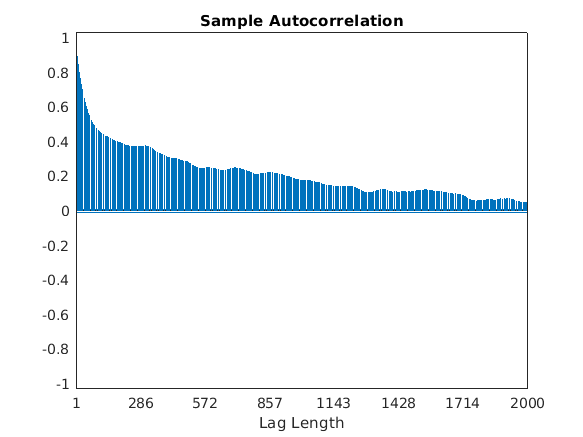


% Plotting
figure(1); clf

% Sample autocorrelation plot
%subplot(1, 2, 1)
lag = 2000;
acf(wstored3(:, 2), lag);

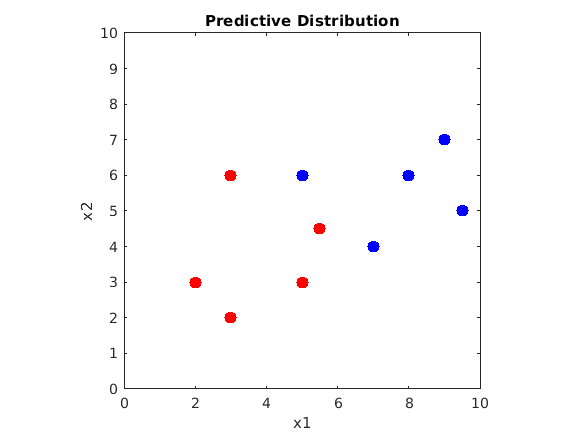


% Predictive distribution plot
%subplot(1,2,2)

% Plott the dots parts
figure(2); clf
plot(X(1:5, 2), X(1:5, 3), 'r.', 'MarkerSize', 30); % rows 1:5 in data have points belonging to left group
hold on
plot(X(6:10, 2), X(6:10, 3), 'b.', 'MarkerSize', 30) % the rows 6-10 have points belonging to different group
xlim([0 10]);
ylim([0 10]); 
axis square
title('Predictive Distribution'); xlabel('x1'); ylabel('x2')
hold on

% Getting the test data
x1 = linspace(0, 10);
x2 = x1; 
[x1 x2] = meshgrid(x1, x2);

xs = [ones(10000, 1), x1(:), x2(:)];

% Calculate learned Y's
learnedY_values = reshape(learnedY_next(xs), 100, 100)

learnedY_values =     0.0042    0.0045    0.0049    0.0053    0.0057    0.0061    0.0066    0.0071    0.0076    0.0082    0.0088    0.0095    0.0102    0.0109    0.0116    0.0124    0.0132    0.0141    0.0150    0.0159    0.0169    0.0180    0.0191    0.0202    0.0214    0.0227    0.0241    0.0255    0.0271    0.0289    0.0308    0.0328    0.0351    0.0375    0.0402    0.0431    0.0462    0.0495    0.0530    0.0566    0.0605    0.0646    0.0689    0.0735    0.0785    0.0841    0.0902    0.0971    0.1048    0.1134
    0.0039    0.0042    0.0046    0.0049    0.0053    0.0057    0.0062    0.0066    0.0072    0.0077    0.0083    0.0089    0.0095    0.0102    0.0109    0.0117    0.0125    0.0133    0.0142    0.0151    0.0161    0.0171    0.0182    0.0193    0.0205    0.0217    0.0231    0.0245    0.0261    0.0278    0.0296    0.0316    0.0338    0.0363    0.0389    0.0417    0.0448    0.0481    0.0516    0.0553    0.0592    0.0634    0.0678    0.0725    0.0776    0.0832    0.0894    0.0963 

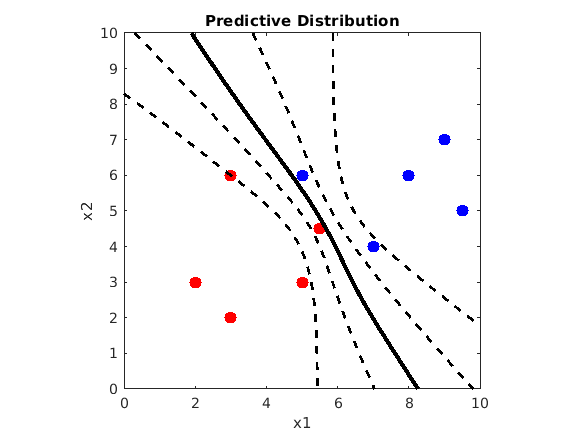

% NOTE: x1, x2, learnedYs are all 100 x 100 matrices
contour(x1, x2, learnedY_values, 5, '--k', 'LineWidth', 2); 
hold on
contour(x1, x2, learnedY_values, 1,'k', 'LineWidth', 3); % [0.5 0.5] in place of 1

## Another way to calculate learned Y's :) 

% size(xs) = 1000 x 3
% size(windep2) = 30 x 3
learnedY_values2 = sum(sigmoid(windep3 * xs')) / length(windep3)

learnedY_values2 =     0.0042    0.0039    0.0037    0.0035    0.0033    0.0031    0.0030    0.0028    0.0027    0.0027    0.0026    0.0026    0.0025    0.0025    0.0025    0.0026    0.0026    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0033    0.0034    0.0036    0.0038    0.0040    0.0042    0.0044    0.0047    0.0050    0.0053    0.0056    0.0059    0.0063    0.0067    0.0071    0.0075    0.0080    0.0085    0.0090    0.0096    0.0102    0.0108    0.0115    0.0123    0.0131    0.0140    0.0150


% or just take the mean:   mean(sigmoid(windep2 * xs'))

% This is the predicted probabilities of target being equal to one. 

learnedY_values2 = reshape(learnedY_values2, 100, 100);

% Plot the dots and learnedYs2 again

figure(3); clf
plot(X(1:5, 2), X(1:5, 3), 'r.', 'MarkerSize', 30); % rows 1:5 in data have points belonging to left group
hold on
plot(X(6:10, 2), X(6:10, 3), 'b.', 'MarkerSize', 30) % the rows 6-10 have points belonging to different group
xlim([0 10]);
ylim([0 10]); 
axis square
title('Predictive Distribution'); xlabel('x1'); ylabel('x2')
hold on
% NOTE: x1, x2, learnedYs are all 100 x 100 matrices
contour(x1, x2, learnedY_values2, 5, '--k', 'LineWidth', 2); 
hold on
contour(x1, x2, learnedY_values2, 1,'k', 'LineWidth', 3); % [0.5 0.5] in place of 1

## Calculated predicted probabilities (mean of learnedY) using my function

% Getting the test data
x1 = linspace(0, 10);
x2 = x1; 
[x1 x2] = meshgrid(x1, x2);

xs = [ones(10000, 1), x1(:), x2(:)];

probabilities = targetProbBayesSingleNeuron(X, targets, xs);

Acceptance rate = 0.497536 


probabilities(1:10)

ans =     0.0042    0.0039    0.0037    0.0035    0.0033    0.0031    0.0030    0.0028    0.0027    0.0027



% Plotting again
figure(3); clf
plot(X(1:5, 2), X(1:5, 3), 'r.', 'MarkerSize', 30); % rows 1:5 in data have points belonging to left group
hold on
plot(X(6:10, 2), X(6:10, 3), 'b.', 'MarkerSize', 30) % the rows 6-10 have points belonging to different group
xlim([0 10]);
ylim([0 10]); 
axis square
title('Predictive Distribution'); xlabel('x1'); ylabel('x2')
hold on

% NOTE: x1, x2, probs/learnedYs are all 100 x 100 matrices
% need to reshape so probs are also 100 x 100
probabilities = reshape(probabilities, 100, 100); 
contour(x1, x2, probabilities, 5, '--k', 'LineWidth', 2); 
hold on
contour(x1, x2, probabilities, 1,'k', 'LineWidth', 3); % [0.5 0.5] in place of 1